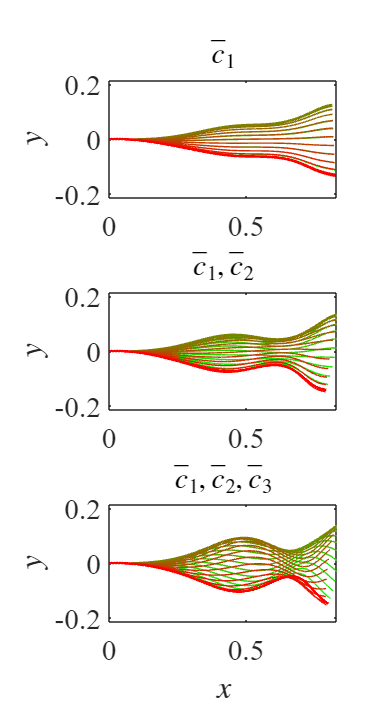

% addpath('.\Data',  '.\Functions',  '.\Images',  '.\Movies')
addpath('Data',  'Functions',  'Images',  'Movies')

if ~exist('coeff_op', 'var')
    load('data_pca_2kModes_vShort.mat', 'coeff_op', 'modes_op', 'mu_op')
end

coeff_dup = coeff_op(:,1:3); % duplicating the 'coeff' matrix

periods_to_run = 2; % for how many time periods do you want to visualize the beat

 

start_ind = 1;
end_ind   = 100;

ind_skip = 1;

nCol = numel(start_ind:ind_skip:end_ind);

startCol = [0 255 0]/255;
endCol   = [255 0 0]/255;

cols_r = linspace(startCol(1), endCol(1), nCol);
cols_g = linspace(startCol(2), endCol(2), nCol);
cols_b = linspace(startCol(3), endCol(3), nCol);

mu_x = mu_op(1:1000);
mu_y = mu_op(1001:2000);

c1_mat = reshape(coeff_dup(:,1),[100, 216]); c1_bar = mean(c1_mat, 2);
c2_mat = reshape(coeff_dup(:,2),[100, 216]); c2_bar = mean(c2_mat, 2);
c3_mat = reshape(coeff_dup(:,3),[100, 216]); c3_bar = mean(c3_mat, 2);

figure
set(gcf, 'position', [607    66   388   707])

ax1 = subplot(3,1,1);
ax2 = subplot(3,1,2);
ax3 = subplot(3,1,3);

for pp = 1:periods_to_run

    for i = start_ind:ind_skip:end_ind

        plotCol = [cols_r( (i-1)/ind_skip + 1 ), cols_g( (i-1)/ind_skip + 1 ), cols_b( (i-1)/ind_skip + 1 )];

        if pp == 1

            if mod(i,4) == 0

                ax1 = subplot(3,1,1);
                h11 = plot( c1_bar(i) * modes_op(1:1000,1) + mu_x', c1_bar(i) * modes_op(1001:2000,1) + mu_y', 'color', plotCol, 'LineWidth', 0.5); hold all
                daspect([1 1 1])

                ax2 = subplot(3,1,2);
                h12 = plot( c1_bar(i) * modes_op(1:1000,1) + c2_bar(i) * modes_op(1:1000,2) + mu_x', ...
                    c1_bar(i) * modes_op(1001:2000,1) + c2_bar(i) * modes_op(1001:2000,2) + mu_y', 'color', plotCol, 'LineWidth', 0.5); hold all
                daspect([1 1 1])

                ax3 = subplot(3,1,3);
                h13 = plot( c1_bar(i) * modes_op(1:1000,1) + c2_bar(i) * modes_op(1:1000,2) + c3_bar(i) * modes_op(1:1000,3) + mu_x', ...
                    c1_bar(i) * modes_op(1001:2000,1) + c2_bar(i) * modes_op(1001:2000,2) + c3_bar(i) * modes_op(1001:2000,3) + mu_y', 'color', plotCol, 'LineWidth', 0.5); hold all
                daspect([1 1 1])

            end

        else

            if i > 1
                delete(h21)
                delete(h22)
                delete(h23)
            elseif i == 1 && pp > 2
                delete(h21)
                delete(h22)
                delete(h23)
            end

            ax1 = subplot(3,1,1);
            h21 = plot( c1_bar(i) * modes_op(1:1000,1) + mu_x', c1_bar(i) * modes_op(1001:2000,1) + mu_y', 'color', plotCol, 'LineWidth', 2); hold all
            daspect([1 1 1])

            ax2 = subplot(3,1,2);
            h22 = plot( c1_bar(i) * modes_op(1:1000,1) + c2_bar(i) * modes_op(1:1000,2) + mu_x', ...
                c1_bar(i) * modes_op(1001:2000,1) + c2_bar(i) * modes_op(1001:2000,2) + mu_y', 'color', plotCol, 'LineWidth', 2); hold all
            daspect([1 1 1])

            ax3 = subplot(3,1,3);
            h23 = plot( c1_bar(i) * modes_op(1:1000,1) + c2_bar(i) * modes_op(1:1000,2) + c3_bar(i) * modes_op(1:1000,3) + mu_x', ...
                c1_bar(i) * modes_op(1001:2000,1) + c2_bar(i) * modes_op(1001:2000,2) + c3_bar(i) * modes_op(1001:2000,3) + mu_y', 'color', plotCol, 'LineWidth', 2); hold all
            daspect([1 1 1])

        end

        xlabel( ax3, '$x$', 'interpreter', 'latex', 'fontsize', 22 );
        ylabel( [ax1, ax2, ax3], '$y$', 'interpreter', 'latex', 'fontsize', 22 );
        set( [ax1 ax2 ax3], 'fontsize', 22, 'fontname', 'times new roman' );

        title(ax1, '$\bar{c}_1$', 'interpreter', 'latex', 'fontsize', 22 )
        title(ax2, '$\bar{c}_1, \bar{c}_2$', 'interpreter', 'latex', 'fontsize', 22 )
        title(ax3, '$\bar{c}_1, \bar{c}_2, \bar{c}_3$', 'interpreter', 'latex', 'fontsize', 22 )

        ax1.XLim = [0 0.83];
        ax1.YLim = [-0.2155 0.2155];

        ax2.XLim = [0 0.83];
        ax2.YLim = [-0.2155 0.2155];

        ax3.XLim = [0 0.83];
        ax3.YLim = [-0.2155 0.2155];

        shg
        pause(0.01)

    end

end